# Classical Control Systems Example Live Script

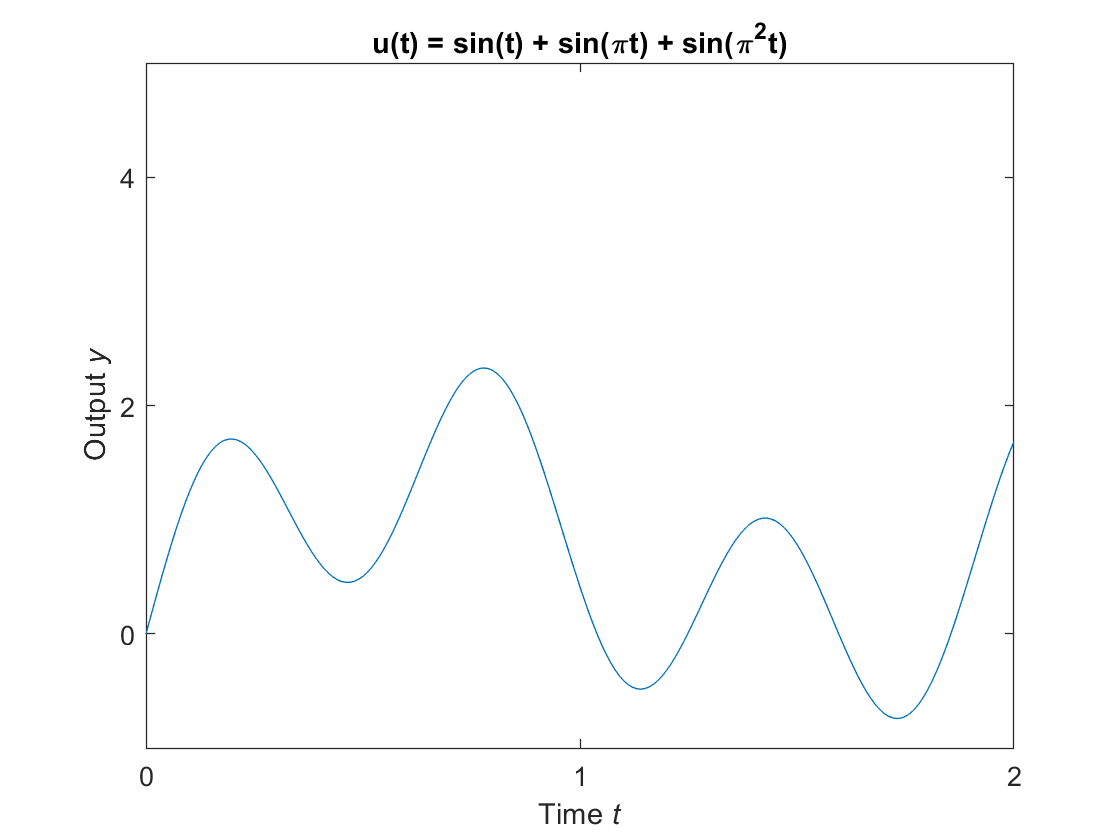

t = 0:1/100:2;
u = sin(t) + sin(pi.*t) + sin(pi^2.*t);
figure
plot(t,u)
xlabel("Time \it{t}")
ylabel("Output \it{y}")
ylim([-1 5])
yticks(-2:2:4)
xticks(0:1:2)
title("u(t) = sin(t) + sin(\pit) + sin(\pi^{2}t)")

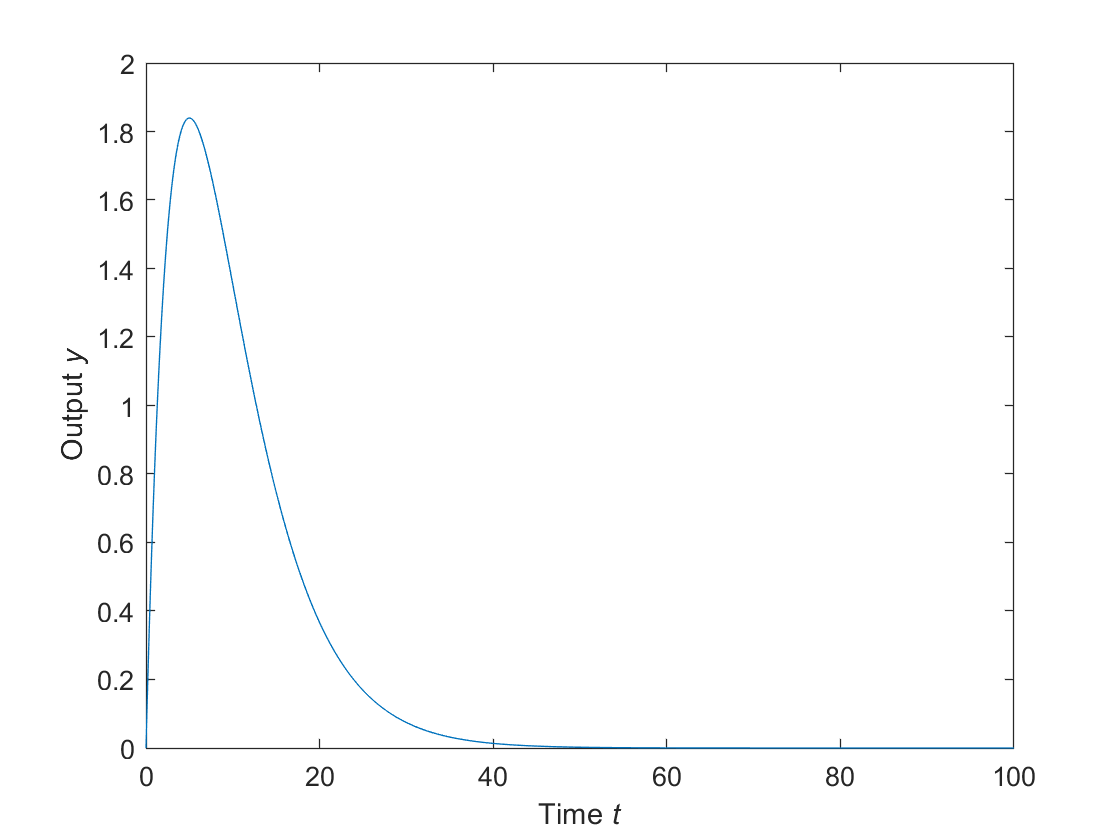


t1 = 0:1/10:100; a = -0.2;
u1 = t1.*exp(a.*t1);
figure
plot(t1,u1)
xlabel("Time \it{t}")
ylabel("Output \it{y}")

s = tf('s'); T = 25; 
G = exp(-s*T)

G =
 
  exp(-25*s) * (1)
 
Continuous-time transfer function.



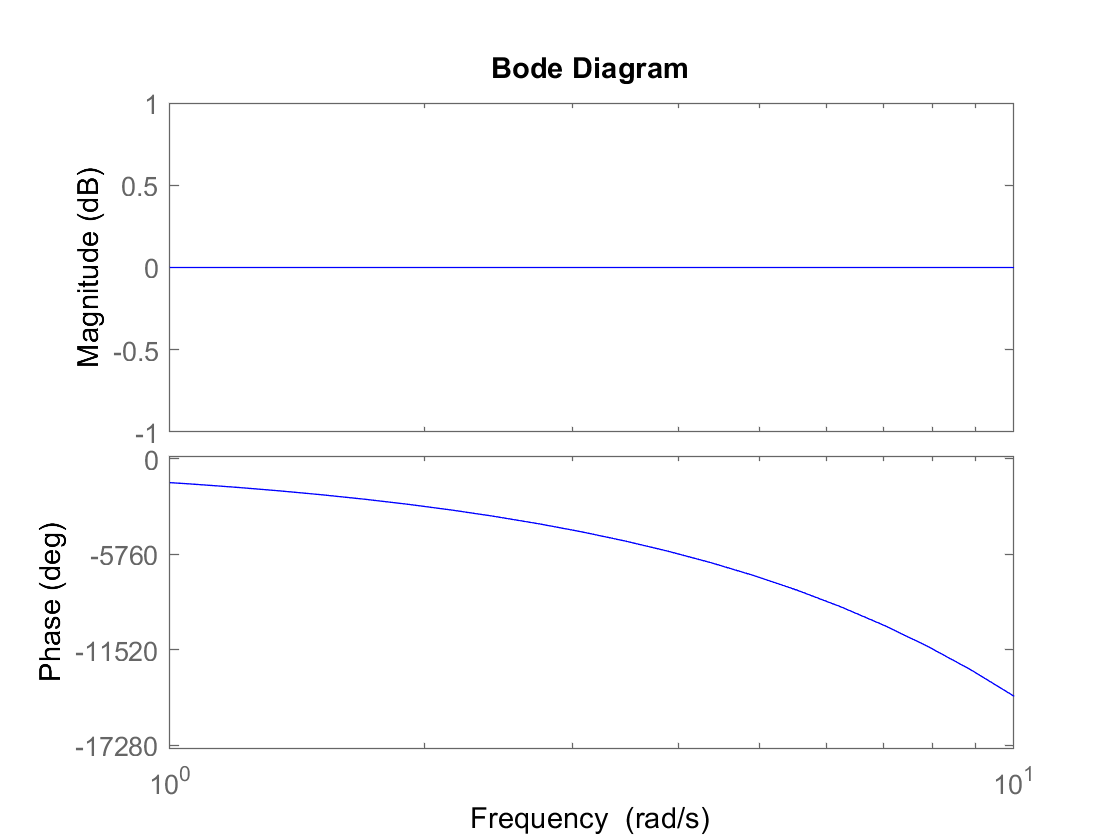

figure, G_bode = bodeplot(G,'b'); 

syms s w
G = exp(-s*T)

$$G = {\mathrm{e}}^{-25\,s}$$

G_w = subs(G,s,j*w)

$$G\_w = {\mathrm{e}}^{-25\,w\,\mathrm{i}}$$

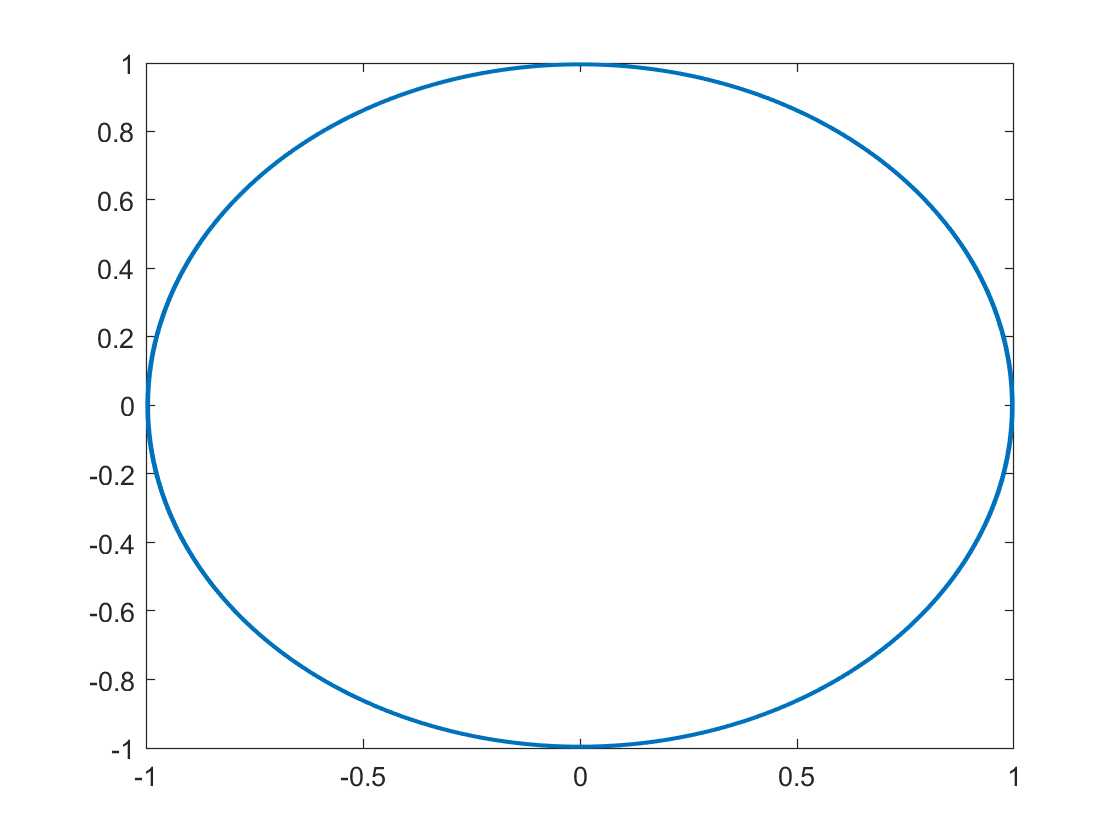

W = -100:.01:100; 
Nyq = eval(subs(G_w,w,W));
x = real(Nyq);
y = imag(Nyq);
figure, plot(x,y)